Mikołaj Suchoń Lab 10

Task 1

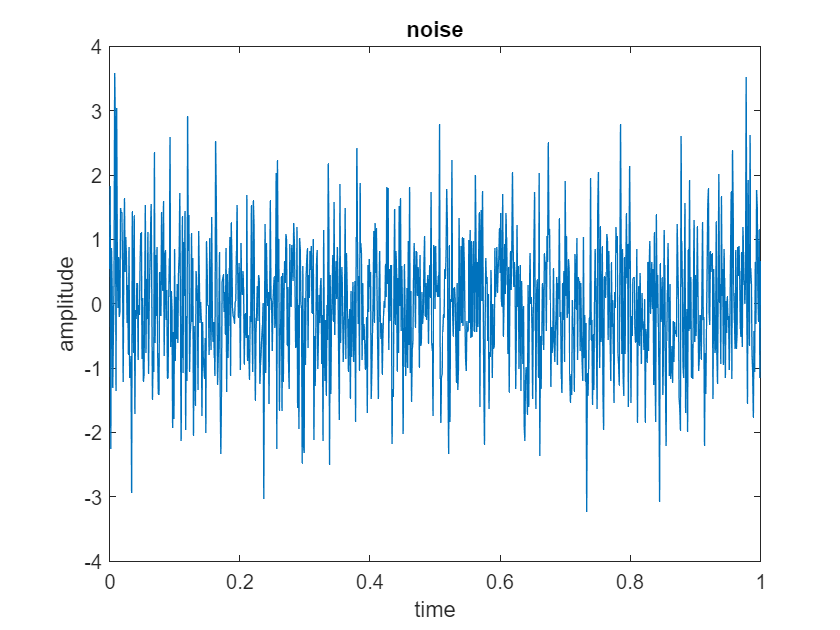

clear
fs=1000;
dt=1/fs;
t=0:dt:1;
%gaussian noise
f1=wgn(1001,1,0)';
plot(t,f1);title('noise');xlabel('time');ylabel('amplitude')

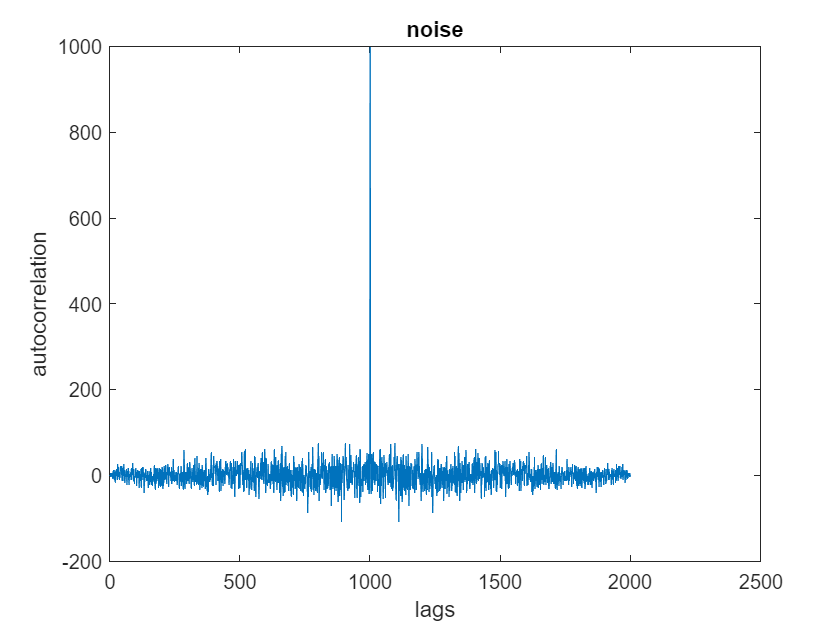

plot(xcorr(f1,f1));title('noise');xlabel('lags');ylabel('autocorrelation')

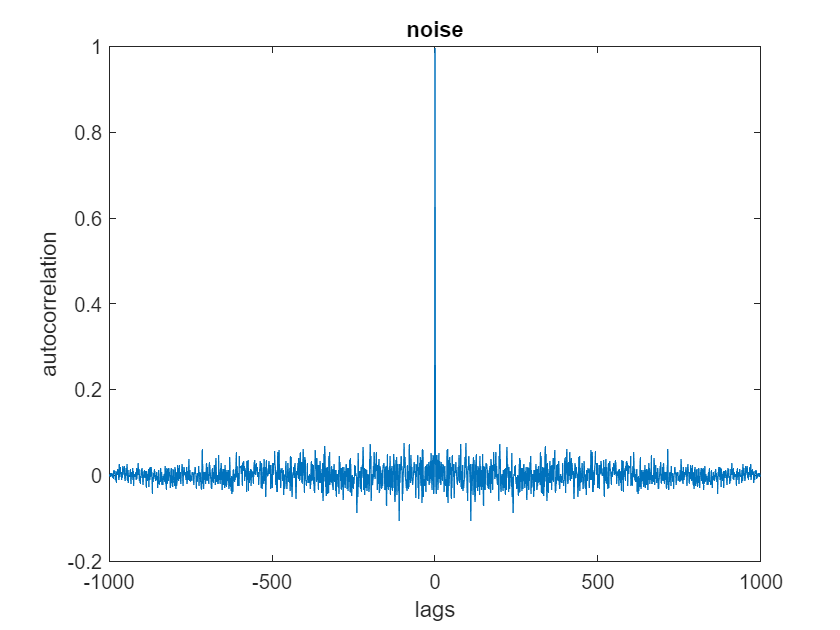

[C,lags] = xcorr(f1,f1,'biased'); plot(lags,C);title('noise');xlabel('lags');ylabel('autocorrelation')

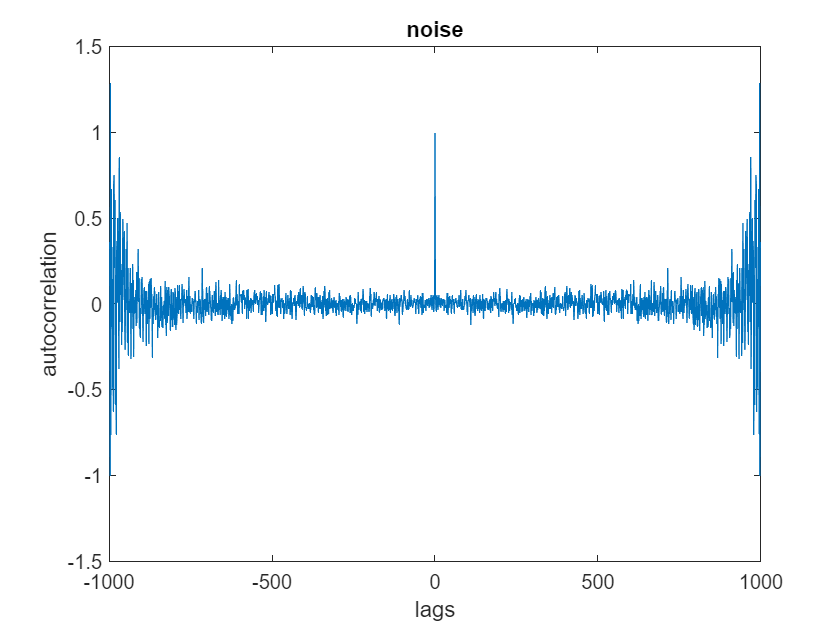

[C,lags] = xcorr(f1,'unbiased'); plot(lags,C);title('noise');xlabel('lags');ylabel('autocorrelation')

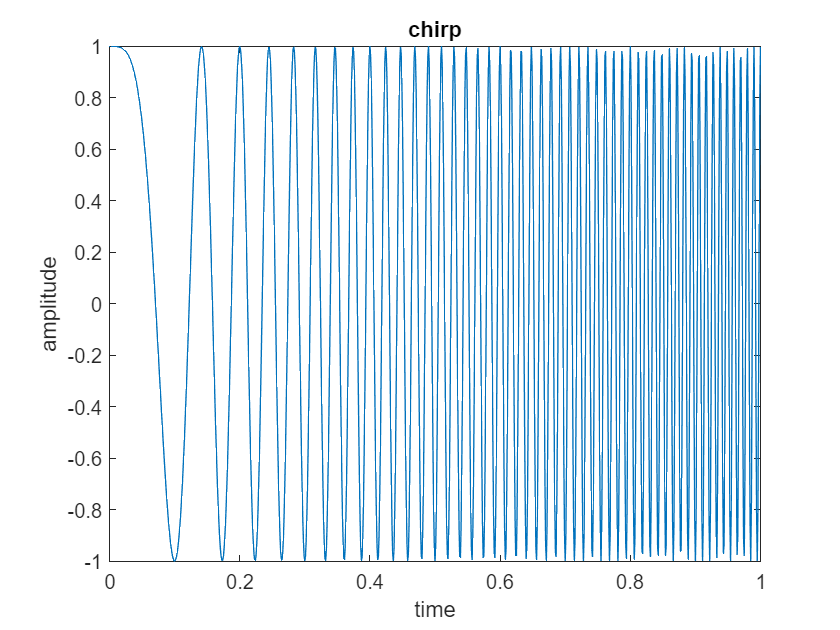

%chirp
f2=chirp(t,0,1);
plot(t,f2);title('chirp');xlabel('time');ylabel('amplitude')

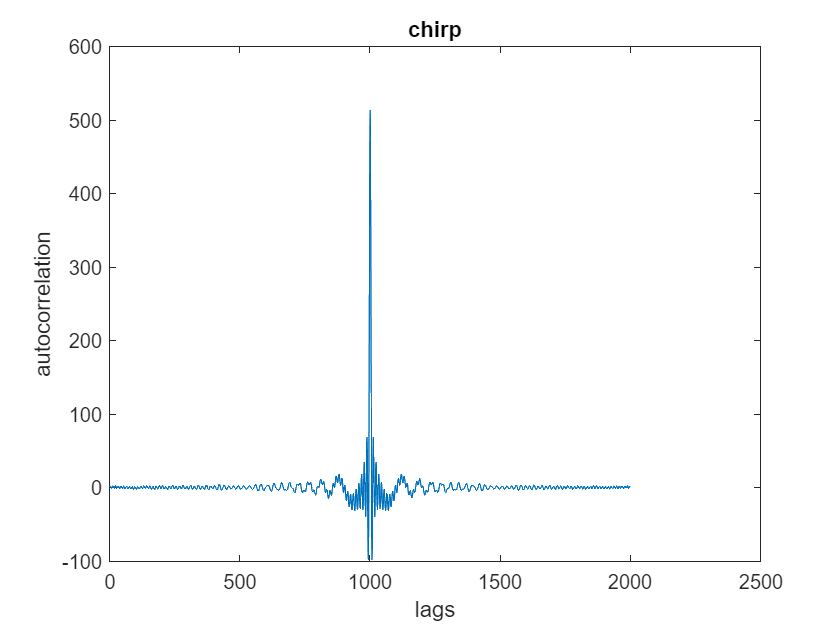

plot(xcorr(f2,f2));title('chirp');xlabel('lags');ylabel('autocorrelation')

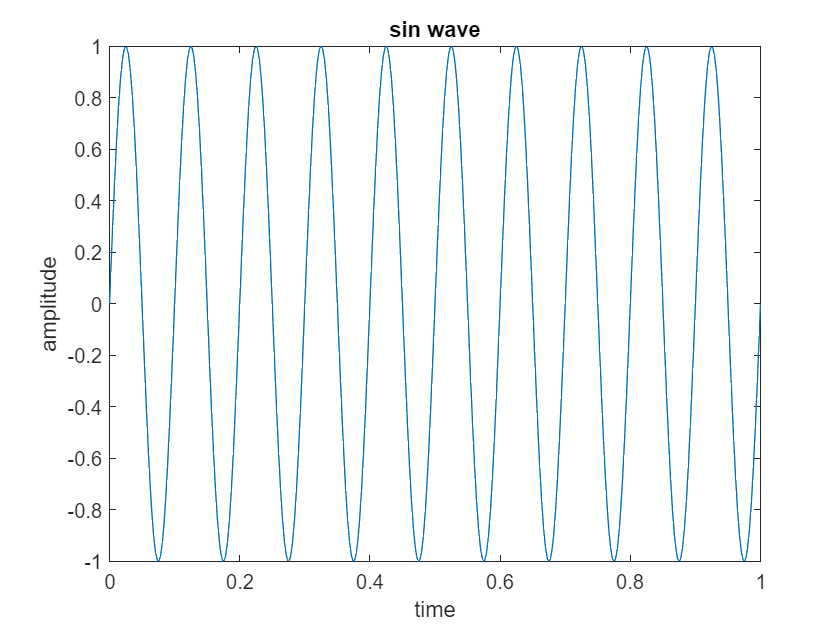

%sine
f3=sin(2*pi*10*t);
plot(t,f3);title('sin wave');xlabel('time');ylabel('amplitude')

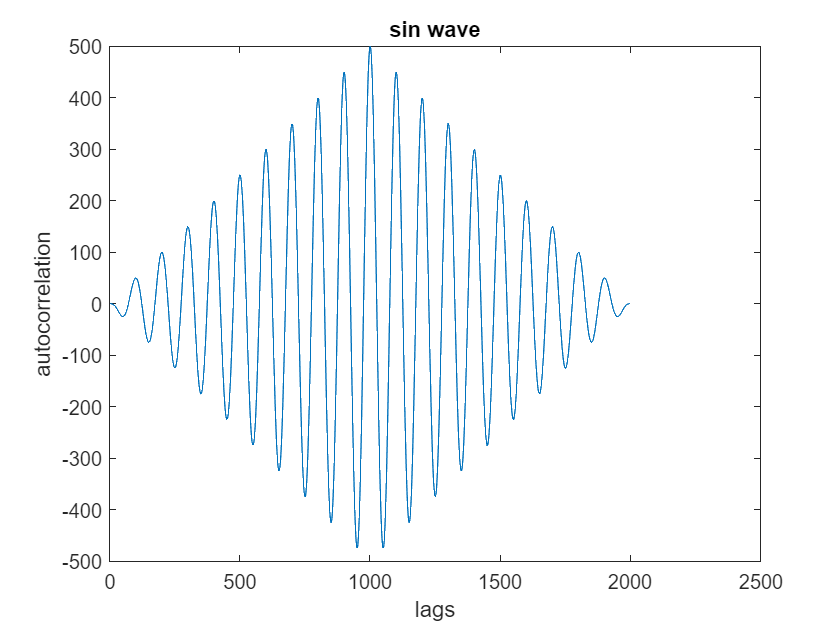

plot(xcorr(f3,f3));title('sin wave');xlabel('lags');ylabel('autocorrelation')

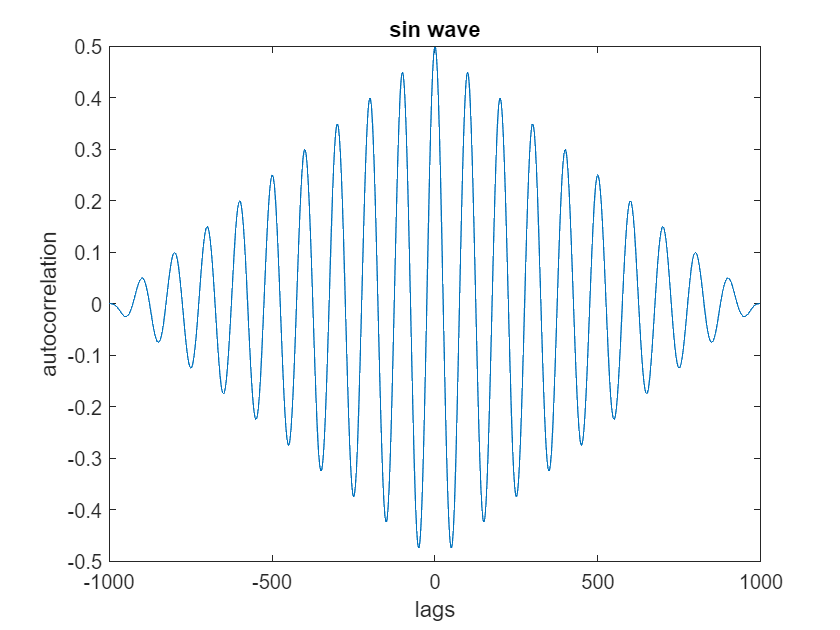

[C,lags] = xcorr(f3,'biased'); plot(lags,C);title('sin wave');xlabel('lags');ylabel('autocorrelation')

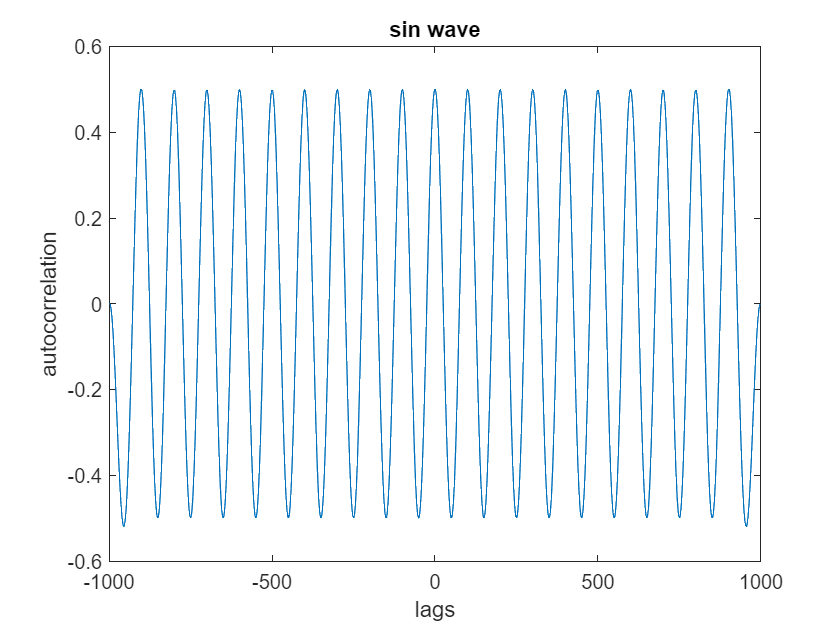

[C,lags] = xcorr(f3,'unbiased'); plot(lags,C);title('sin wave');xlabel('lags');ylabel('autocorrelation')

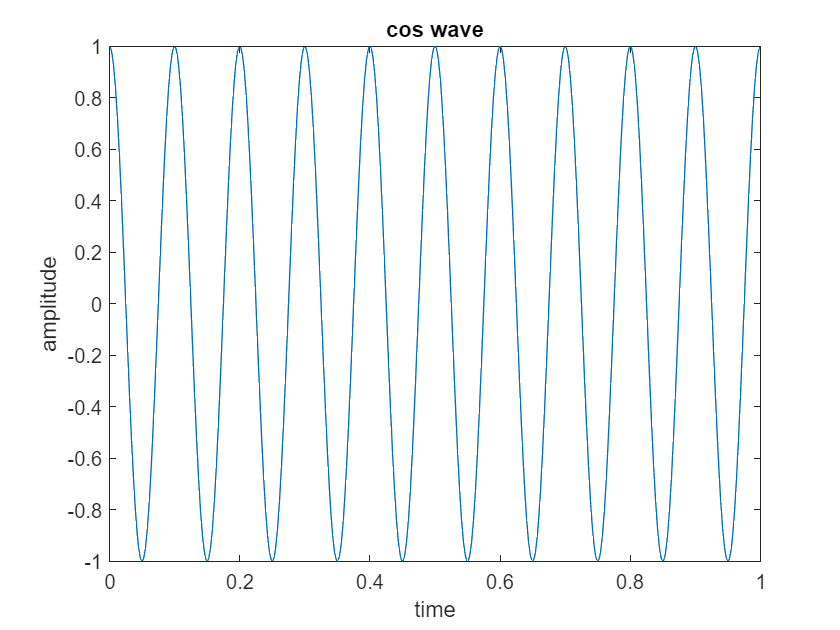

%cosine
f4=cos(2*pi*10*t);
plot(t,f4);title('cos wave');xlabel('time');ylabel('amplitude')

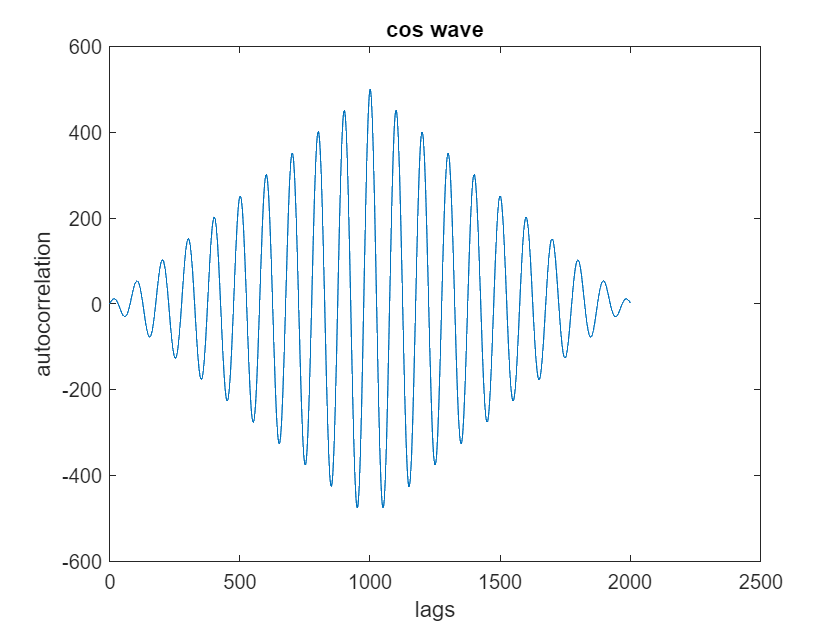

plot(xcorr(f4,f4));title('cos wave');xlabel('lags');ylabel('autocorrelation')

Task 2

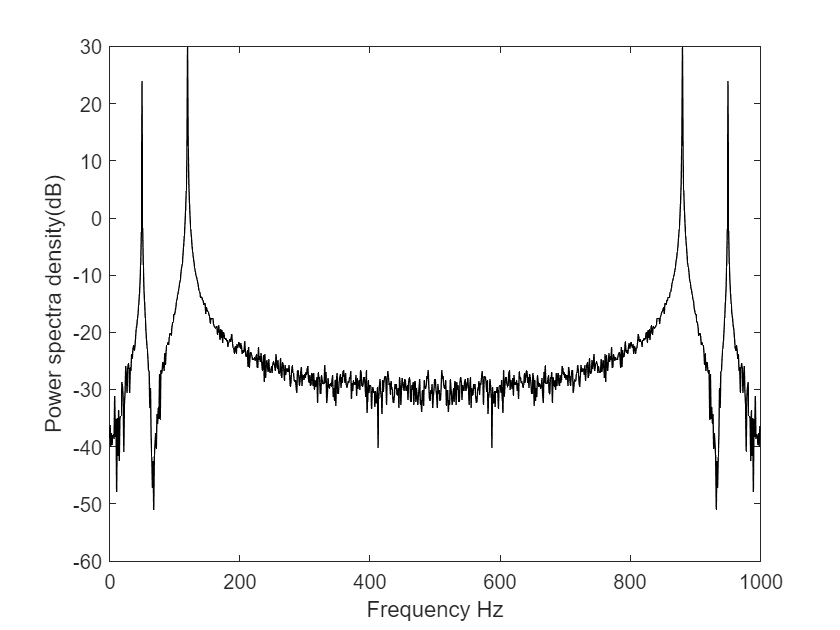

clear
fs=1000;
dt=1/fs;
t=0:dt:1;
f1=sin(2*pi*50*t)+2*sin(2*pi*120*t)+0.01*randn(size(t));
N=length(f1); df=fs/N; f=df*(0:N-1);
Pxx=abs(fft(f1)).^2/N;

plot(f,10*log10(Pxx),'black')
xlabel('Frequency Hz'), ylabel('Power spectra density(dB)');


var(fft(f1))

ans = 2.5031e+03

var(fft(f1(1:500)))

ans = 1.2522e+03

var(fft(f1(1:250)))

ans = 626.9599

The longer the signal the higher the variance

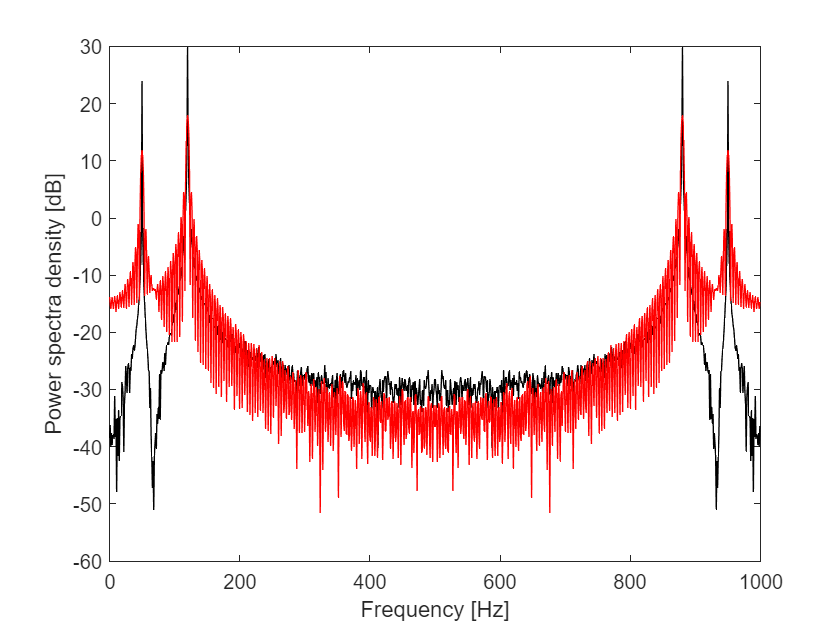

plot(f,10*log10(Pxx),'black');hold on;
pxx=abs(fft(f1(1:250),N)).^2/N;
plot(f,10*log10(pxx),'r')
xlabel('Frequency [Hz]'), ylabel('Power spectra density [dB]');hold off

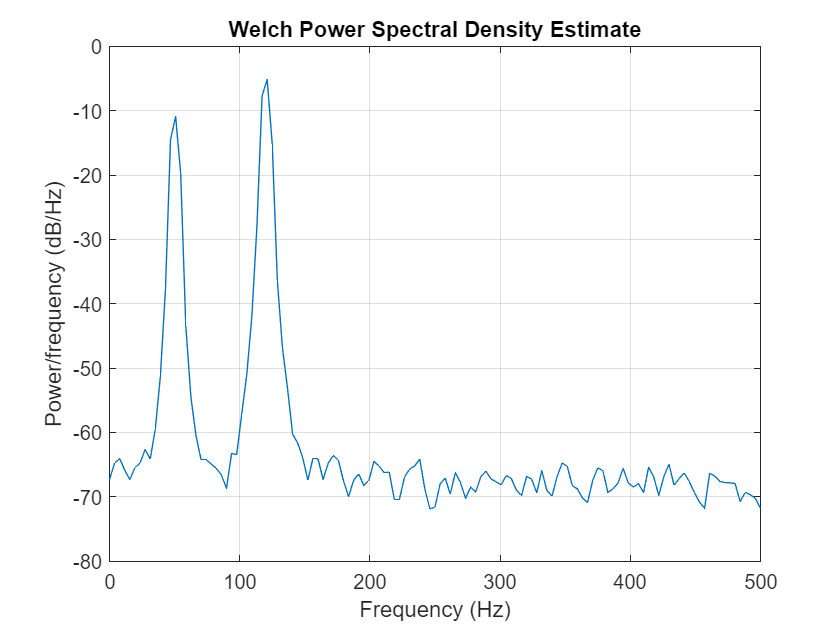

pwelch(f1,hanning(256),[],256,fs);

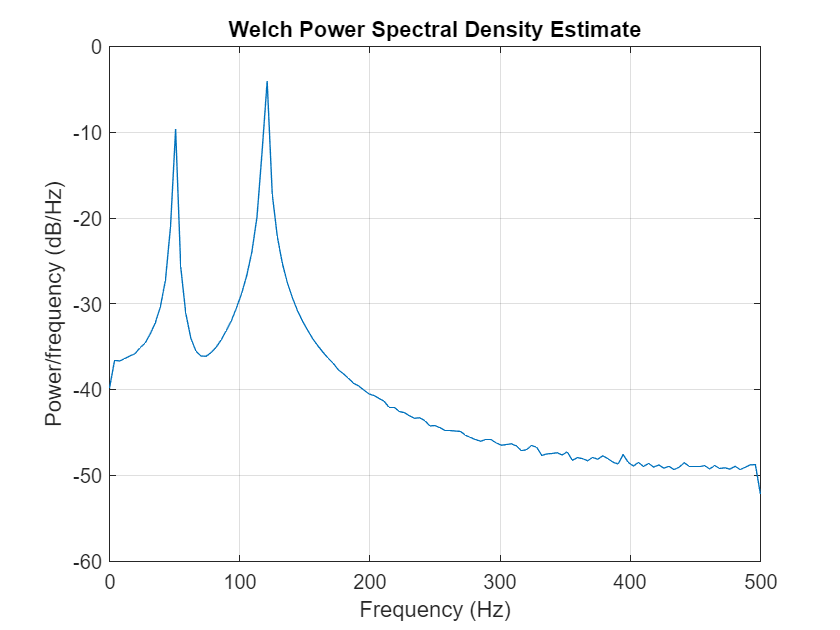

pwelch(f1,rectwin(256),128,256,fs);

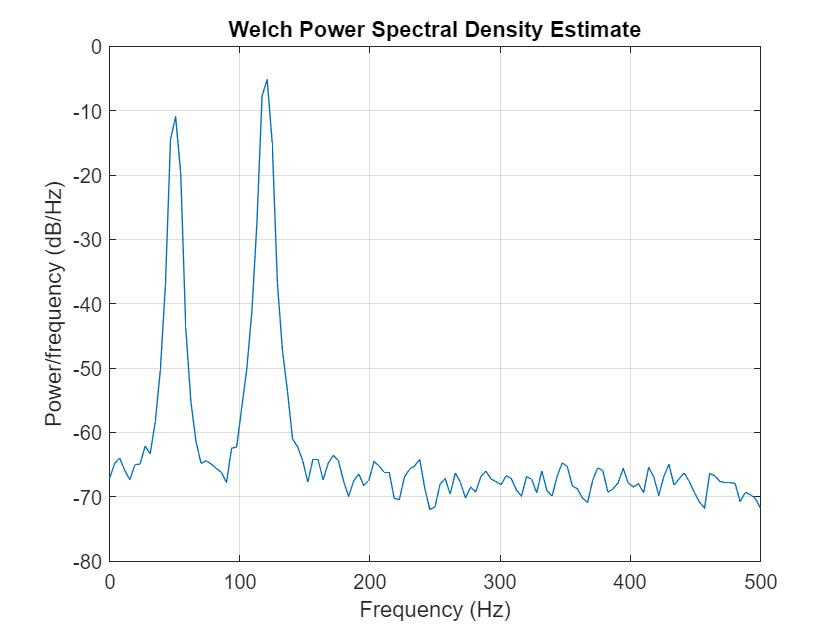

pwelch(f1,hann(256),128,256,fs);

Power calculation

[P,F] = pwelch(f1,rectwin(N),[],N,fs);
[Pxx,f]=periodogram(f1,rectwin(N),[],fs);
sum(f1.^2)/N

ans = 2.4981

sum(P)

ans = 2.5006

sum(Pxx)/1001*fs

ans = 2.5555

All three methods are accurate to 0.1

To compute average power of a specific frequency we consider windows of signal and compute power for each segment to sum them up.

Task 3

clear
c1 = 0.7;
c2 = 0.9;
c3 = 0.7;
k1 = 120 ;
k2 = 200;
k3 = 170;
m1 = 10;
m2 = 7;


fs=1000;
N=10^5; 
t=1/fs*(0:N-1);
f=fs/N*(0:N-1);

A = [0 0 1 0; 0 0 0 1;...
    -(k1+k2)/m1 k2/m1 -(c1+c2)/m1 c2/m1;...
    k2/m2 -(k2+k3)/m2 c2/m2 -(c2+c3)/m2]

A =          0         0    1.0000         0
         0         0         0    1.0000
  -32.0000   20.0000   -0.1600    0.0900
   28.5714  -52.8571    0.1286   -0.2286


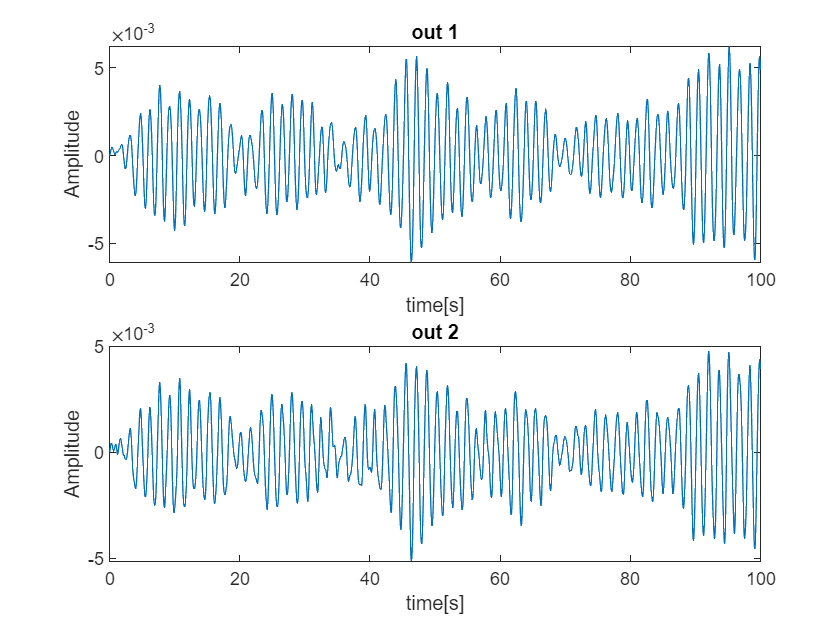

B = [0; 0; 1/m1; 1/m2];
C = [1 0 0 0; 0 1 0 0];
D = [0; 0];

sys = ss(A,B,C,D);
S = tf(sys);

x = randn(1,N);
[y,~]=lsim(S, x, t);
subplot(2,1,1)
plot(t,y(:,1))
xlabel('time[s]')
ylabel('Amplitude')
title('out 1')
subplot(2,1,2)
plot(t,y(:,2))
xlabel('time[s]')
ylabel('Amplitude')
title('out 2')

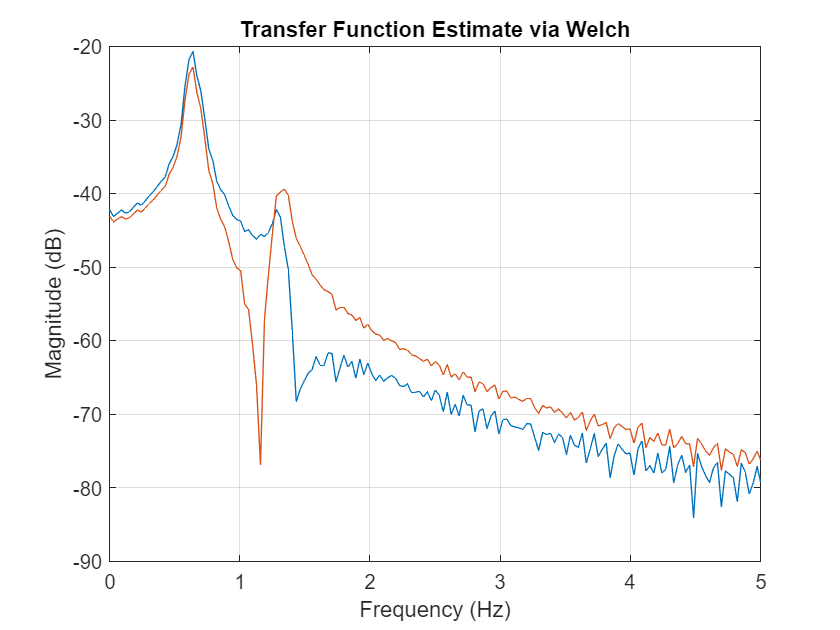

figure
tfestimate(x,y,[],[],[],fs,'mimo')
xlim([0,5])

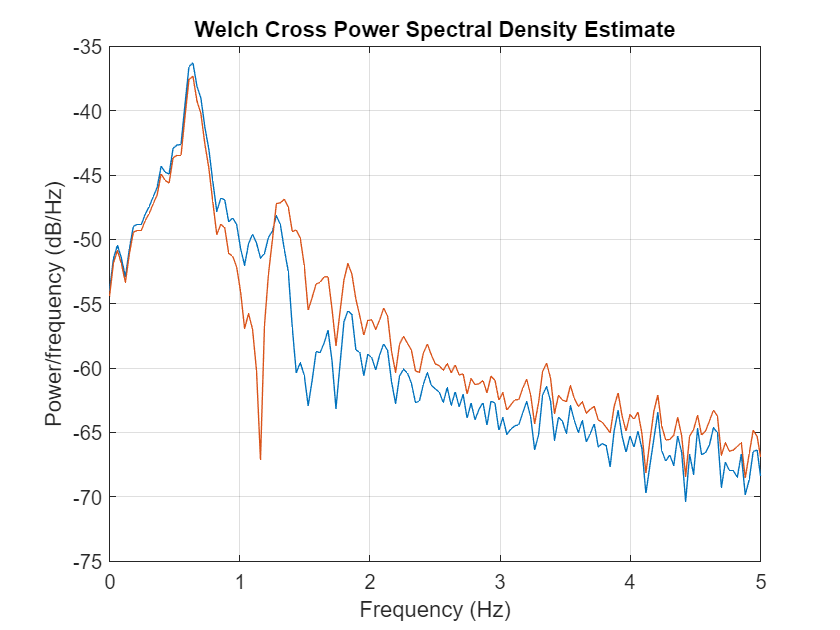

cpsd(x,y,[],[],[],fs)
xlim([0,5])

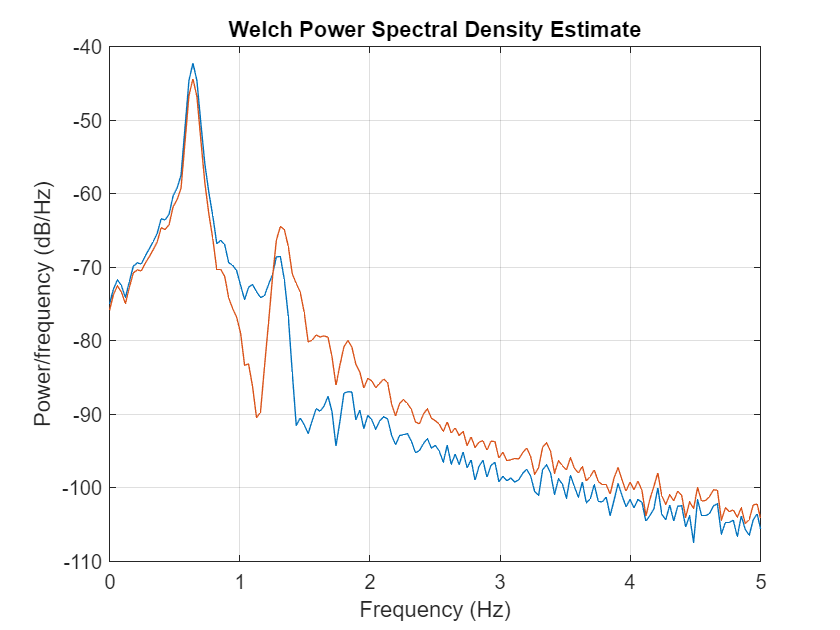

pwelch(y,[],[],[],fs)
xlim([0,5])

We confirm that the above system is of 2DOF by two peaks present on plots 

Two natural frequencies are for 0.64 and 1.31 Hz

Task 4

[nat_freq,damp_factor] = damp(S)

nat_freq =     4.0433
    4.0433
    8.2770
    8.2770


damp_factor =     0.0101
    0.0101
    0.0185
    0.0185


nat_freq/(2*pi)

ans =     0.6435
    0.6435
    1.3173
    1.3173


This calculation confirms observation from previous task

Task 5

[wn1,z1]=damp(idss(ar(y(:,2),4)))

wn1 =     0.0041
    0.0041
    1.2410
    1.2410


z1 =     0.0214
    0.0214
    0.7041
    0.7041


[wn2,z2]=damp(idss(armax(y(:,2),[8 8])))

wn2 =     0.0042
    0.0042
    0.0134
    0.7437
    0.7437
    1.7965
    1.7965
    3.1502


z2 =     0.0385
    0.0385
    1.0000
    0.3255
    0.3255
    0.0313
    0.0313
    0.0737


wn1=wn1/(2*pi)*fs

wn1 =     0.6568
    0.6568
  197.5159
  197.5159


wn2=wn2/(2*pi)*fs

wn2 =     0.6607
    0.6607
    2.1389
  118.3625
  118.3625
  285.9177
  285.9177
  501.3624
